# data preprocess

% choose feature i think useful(and easy to work with)
train2=train(:,{'Pclass','Sex','Age','SibSp','Parch','Fare','Embarked','Survived'});
% remove nan
train2=train2(~any(ismissing(train2),2),:);
% the mnr model only accept numbers
[index,~,sex]=unique(train2.Sex);
index

index = 2×1 categorical 数组
     female 
     male 


train2.Sex=sex

train2 = 712×8 table
    Pclass    Sex    Age    SibSp    Parch     Fare     Embarked    Survived
    ______    ___    ___    _____    _____    ______    ________    ________

      3        2     22       1        0        7.25       S           0    
      1        1     38       1        0      71.283       C           1    
      3        1     26       0        0       7.925       S           1    
      1        1     35       1        0        53.1       S           1    
      3        2     35       0        0        8.05       S           0    
      1        2     54       0        0      51.862       S           0    
      3        2      2       3        1      21.075       S           0    
      3        1     27       0        2      11.133       S           1    
      2        1     14       1        0      30.071       C           1    
      3        1      4       1        1        16.7       S           1    
      1        1     58       0        0       26.55  

[index,~,embarked]=unique(train2.Embarked);
index

index = 3×1 categorical 数组
     C 
     Q 
     S 


train2.Embarked=embarked

train2 = 712×8 table
    Pclass    Sex    Age    SibSp    Parch     Fare     Embarked    Survived
    ______    ___    ___    _____    _____    ______    ________    ________

      3        2     22       1        0        7.25       3           0    
      1        1     38       1        0      71.283       1           1    
      3        1     26       0        0       7.925       3           1    
      1        1     35       1        0        53.1       3           1    
      3        2     35       0        0        8.05       3           0    
      1        2     54       0        0      51.862       3           0    
      3        2      2       3        1      21.075       3           0    
      3        1     27       0        2      11.133       3           1    
      2        1     14       1        0      30.071       1           1    
      3        1      4       1        1        16.7       3           1    
      1        1     58       0        0       26.55  

% train test split
[trainInd,valInd,testInd] = dividerand(height(train2),0.8,0,0.2);
realTrain=train2(trainInd,:);
test=train2(testInd,:);
realTrain

realTrain = 570×8 table
    Pclass    Sex    Age    SibSp    Parch     Fare     Embarked    Survived
    ______    ___    ___    _____    _____    ______    ________    ________

      3        2     22       1        0        7.25       3           0    
      1        1     38       1        0      71.283       1           1    
      3        1     26       0        0       7.925       3           1    
      1        1     35       1        0        53.1       3           1    
      3        2     35       0        0        8.05       3           0    
      1        2     54       0        0      51.862       3           0    
      3        2      2       3        1      21.075       3           0    
      3        1     27       0        2      11.133       3           1    
      2        1     14       1        0      30.071       1           1    
      3        1      4       1        1        16.7       3           1    
      1        1     58       0        0       26.5

## fit the model

B=mnrfit(realTrain{:,1:7}, categorical(realTrain{:,8}))

B =    -8.1889
    1.2694
    2.4888
    0.0434
    0.3216
    0.0572
   -0.0008
    0.1654


## predict

pred=mnrval(B,test{:,1:7})

pred =     0.4282    0.5718
    0.9116    0.0884
    0.5640    0.4360
    0.7841    0.2159
    0.6977    0.3023
    0.3225    0.6775
    0.8807    0.1193
    0.1324    0.8676
    0.7412    0.2588
    0.8802    0.1198



pred_survived=pred(:,2)>0.5

pred_survived = 142×1 logical 数组
   1
   0
   0
   0
   0
   1
   0
   1
   0
   0



test{:,8}

ans =      1
     0
     0
     1
     1
     1
     0
     1
     0
     0


% true positive rate
tpr=sum(pred_survived & test{:,8})/sum(test{:,8})

tpr = 0.7500


% result not bad
C = confusionchart(test{:,8}>0.5,pred_survived)

C =   ConfusionMatrixChart - 属性:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 logical]

  显示 所有属性


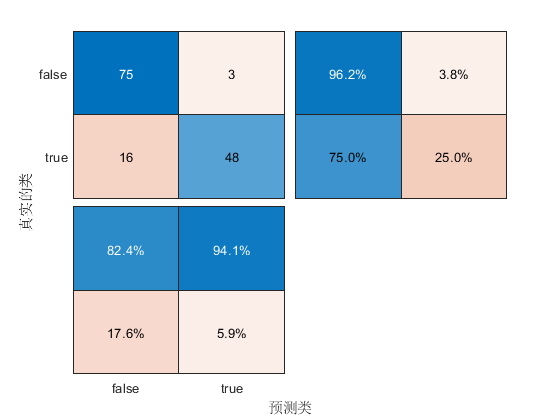

C.RowSummary = 'row-normalized';
C.ColumnSummary = 'column-normalized';